# Digital Signal Processing

# MATLAB HW - q4

Instructor: Professor Sheikhzadeh,  Author: Dina - Soltani Tehrani

E-mail: d.soltani.t@aut.ac.ir

Affiliation: Amirkabir University of Technology

# HW1-Q4

clc; clear; close;
n=-50:50;
u8= [ zeros(1,50) ones(1,51) ];
a8=[4 -2*sqrt(2) 1];
b8=[1 -2*sqrt(2) 4];
h8=filter(b8,a8,n); % impulse response
H8=(freqz(h8))';
h8_step=filter(b8,a8,u8); % impulse response

## Frequency Responce

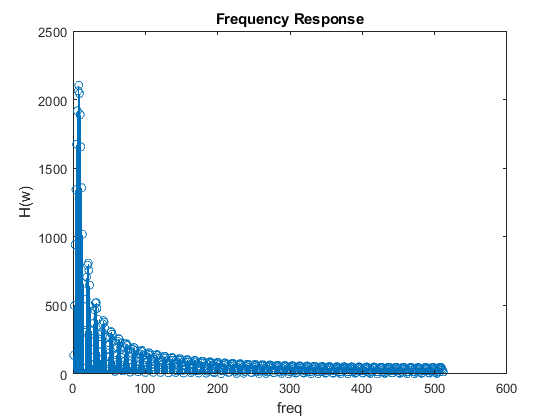

figure(13)
stem(abs(H8))
xlabel('freq'); ylabel('H(w)'); title('Frequency Response');

## Impulse Vs. Step Response

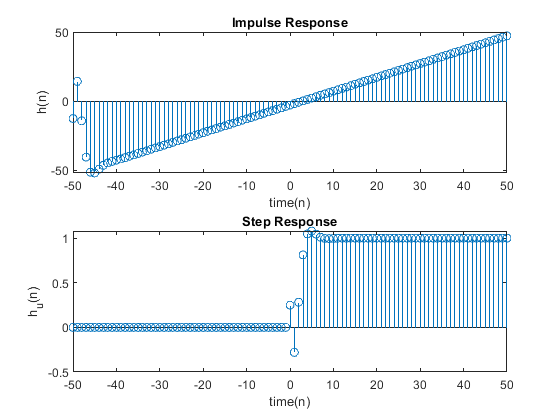

figure(14)
subplot(2,1,1); stem(n,h8)
xlabel('time(n)'); ylabel('h(n)'); title('Impulse Response');
subplot(2,1,2); stem(n,h8_step)
xlabel('time(n)'); ylabel('h_u(n)'); title('Step Response');

## Poles and Zeros

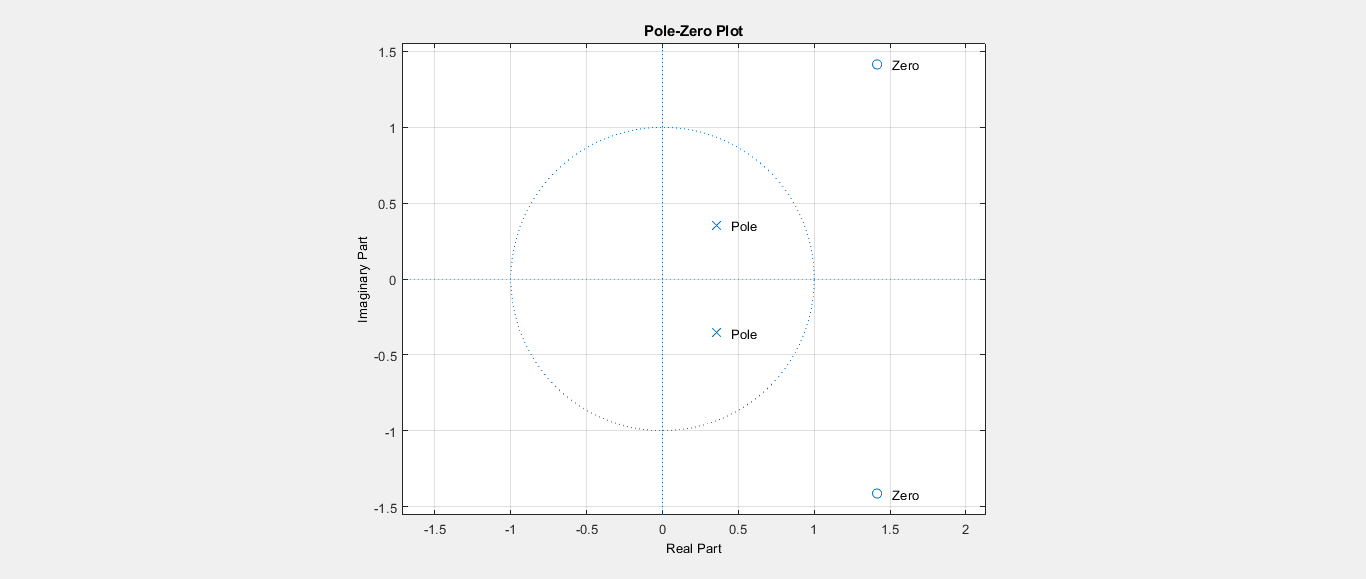

% --
fvtool(b8,a8,'polezero')
[b8,a8] = eqtflength(b8,a8);
[z,p,k] = tf2zp(b8,a8);
text(real(z)+.1,imag(z),'Zero')
text(real(p)+.1,imag(p),'Pole')